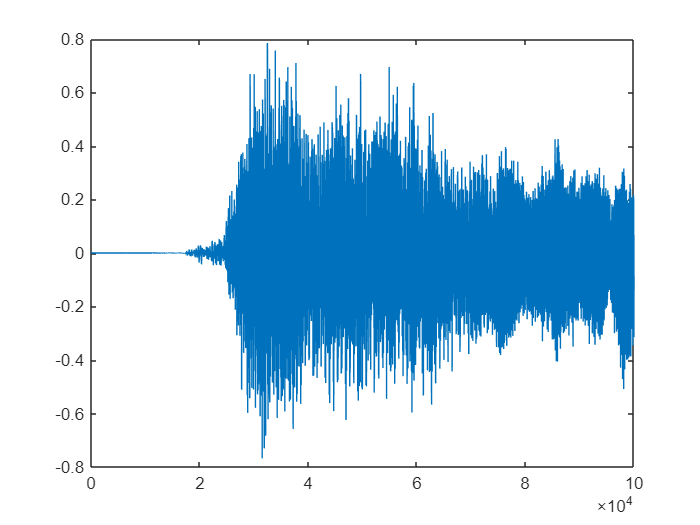

N = 200;  % Filter order
fc = 0.04; % Normalized cutoff frequency (fc/fs)
b = fir1(N-1, fc, hamming(N));

[x,Fs] = audioread('StarWars4_orig.wav'); NBITS=16;

y1 = conv(b,x(:,1));
y2 = conv(b,x(:,2));

figure();
plot([0:100000],x(1:100001,1));

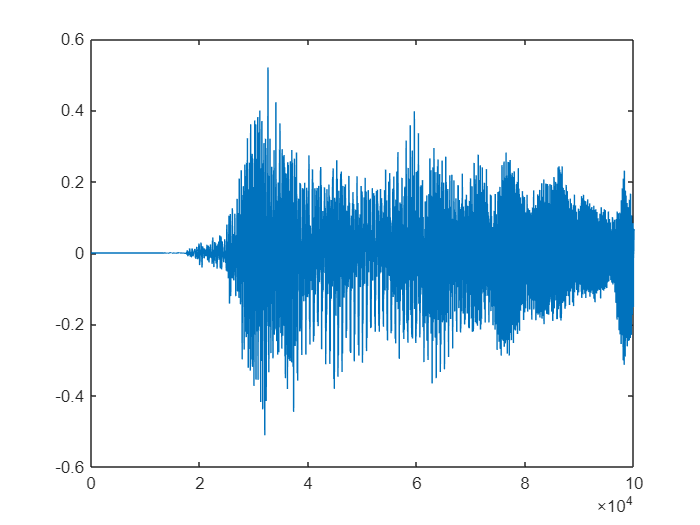

figure();
plot([0:100000],y1(1:100001));

p = audioplayer([y1,y2],Fs); play(p); pause(4);